## Метод разложения из книжки НИКОЛЬСКОГО

Круглый диэлектрический цилиндр, E-поляризаци

Метод разложения в ряд Фурье

25-03-21

close all;
clear variables;

### 1. Входные данные

%%  1 - входные данные  
% Параметры среды-1
e1 = 2.56;
mu1 = 1;
k1 = 2*pi*sqrt(mu1*e1);
eta1 = 120*pi*sqrt(mu1/e1); 

% Параметры среды-2
k2 = 2*pi;
eta2 = 120*pi;

% Параметры программы
a = 5/(2*pi);  % радиус круга 
N_harm = 100; % количество гармоник
N_circl = 100; % количество точек на круга 
phi_i_grad = 0; % угол падения [град]
phi_i_rad = 2*pi/360*phi_i_grad; % угол падения [рад]



### 2. Построение круга

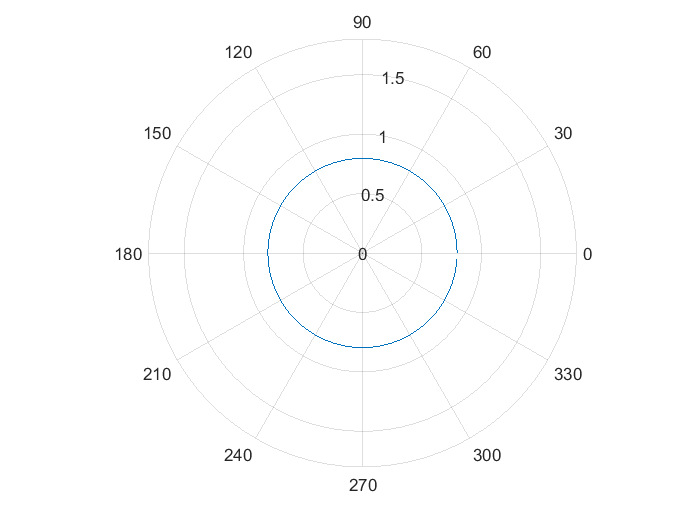

dphi_grad = 360/N_circl; % угловой шаг на круга [град]
dphi_rad = 2*pi/N_circl; % угловой шаг на круга [рад]

% получение векторов углов и вектора ридиусов
phi_circl_rad = zeros(1, N_circl);
phi_circl_grad = zeros(1, N_circl);
a_for_graph = zeros(1, N_circl);
for i = 1 : N_circl
    phi_circl_rad(i) = (i-1)*dphi_rad;
    phi_circl_grad(i) = (i-1)*dphi_grad;
    a_for_graph(i) = a;
end


% """график круга в полярных координатах"""
polarplot(phi_circl_rad, a_for_graph);

### 4. Метод из книжки Никольский

% 4 - посчитаем поле методом никольского на растоянии ro = 2*a
    
% растояние на котром будем смотреть поле
ro = 2*a;

Es_NIC = zeros(1,N_circl);
Hs_NIC = zeros(1,N_circl);
Ep_NIC = zeros(1,N_circl);
Hp_NIC = zeros(1,N_circl);

for n_dot = 1 : N_circl
    
    % текужщий угол
    cur_phi = phi_circl_rad(n_dot);
    
    Es_sum = 0;
    Hs_sum = 0;
    Ep_sum = 0;
    Hp_sum = 0; 
    for n = -N_harm: 1 : N_harm
        
        An = (-1i)^n*exp(-1i*n*phi_i_rad);        
        Z2 = besselj(n,k1*a)*dH(n,k2*a) - eta2/eta1*besselh(n,1,k2*a)*dJ(n,k1*a);     
        bn = An * (dH(n,k2*a)*besselj(n,k2*a) - besselh(n,1,k2*a)*dJ(n,k2*a))/Z2;
        cn = An * (-besselj(n,k1*a)*dJ(n,k2*a) + eta2/eta1*dJ(n,k1*a)*besselj(n,k2*a))/Z2;

        % т.к. есть отрицалеьные гармоники то j(-n,x) = (-1)^n*J(n,x)
        % знак в bn и cn не меняется, НО меняетс в Es,Ep,Hs,Hp - поэт учли
        % его здесь!!!
               
        % отраженое поле
        Es_sum = Es_sum + cn*besselh(n,1,k2*ro)*exp(1i*n*cur_phi);
        Hs_sum = Hs_sum + 1i/eta2*cn*dH(n, k2*ro)*exp(1i*n*cur_phi);
        
        % прошедшее поле
        Ep_sum = Ep_sum + bn*besselj(n, k1*ro)*exp(1i*n*cur_phi);
        Hp_sum = Hp_sum + 1i/eta1*bn*dJ(n, k1*ro)*exp(1i*n*cur_phi);
        
    end
    Es_NIC(n_dot) = Es_sum;
    Hs_NIC(n_dot) = Hs_sum;
    Ep_NIC(n_dot) = Ep_sum;
    Hp_NIC(n_dot) = Hp_sum;
end

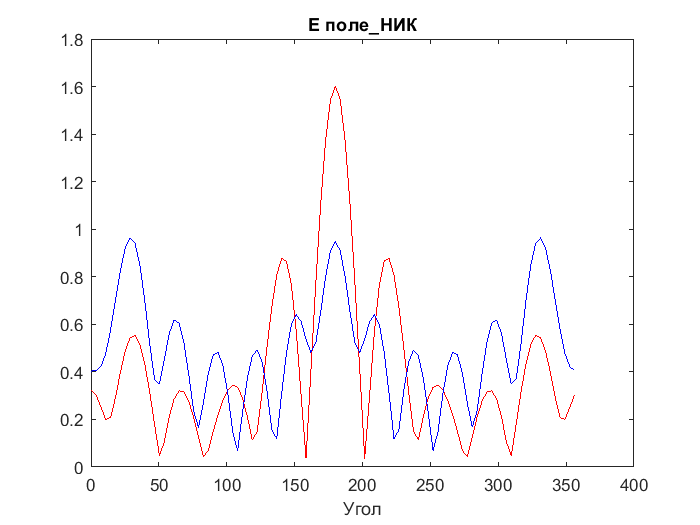

% графики полей 
plot(phi_circl_grad, abs(Es_NIC),'r',phi_circl_grad, abs(Ep_NIC),'b')
title('E поле\_НИК'); 
xlabel('Угол'); 
ylabel('');

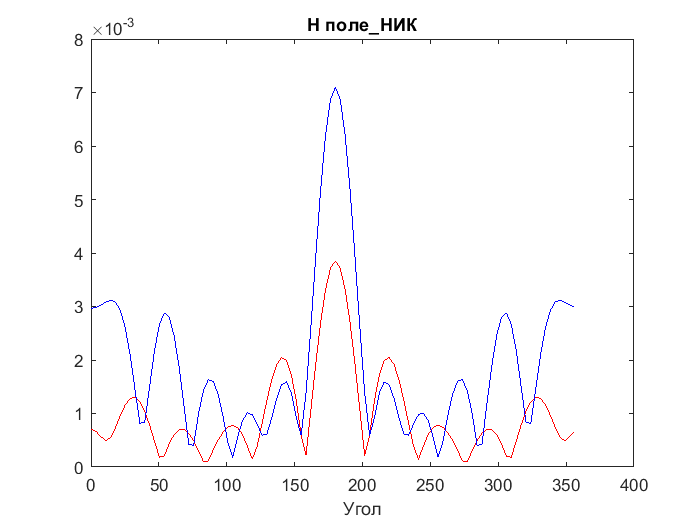


% графики полей 
plot(phi_circl_grad, abs(Hs_NIC),'r',phi_circl_grad, abs(Hp_NIC),'b')
title('H поле\_НИК'); 
xlabel('Угол'); 
ylabel('');

Полярные графики полей

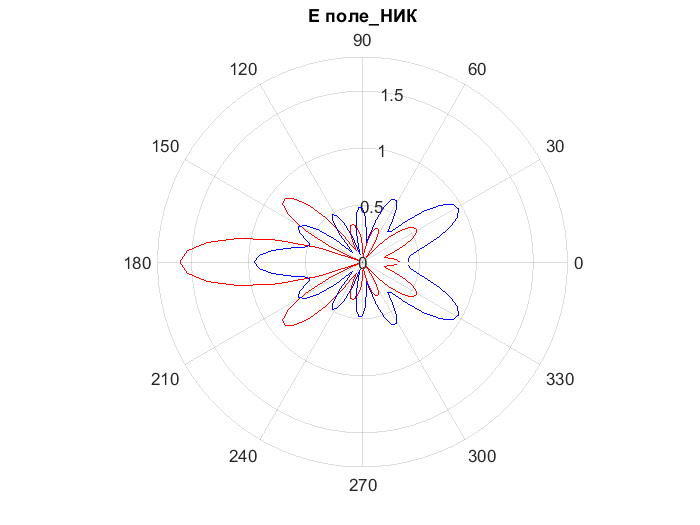

% графики полей 
polarplot(phi_circl_rad, abs(Es_NIC),'r',phi_circl_rad, abs(Ep_NIC),'b')
title('E поле\_НИК'); 

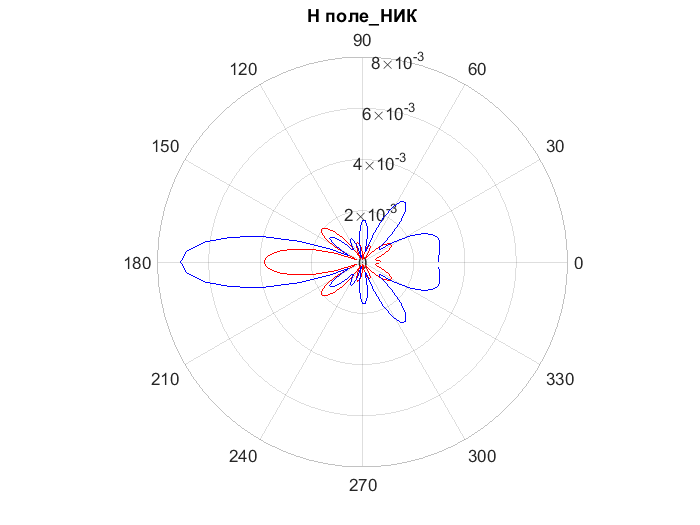



% графики полей 
polarplot(phi_circl_rad, abs(Hs_NIC),'r',phi_circl_rad, abs(Hp_NIC),'b')
title('H поле\_НИК'); 

### ЭПР

RCS = zeros(721,1);
phi_rad_for_graf_DA = zeros(721,1);
phi_grad_for_graf_DA = zeros(721,1);

for p = 1 : 721
    Sum_E = 0;
    curr_phi_grad = (p-1)/2; % угол из формулы для приведения 721 к 360 градусам
    curr_phi_rad = 2*pi/360*curr_phi_grad;
    
    % запищем в массивы для дальнейшего использования
    phi_grad_for_graf_DA(p) = curr_phi_grad; % угол для графика
    phi_rad_for_graf_DA(p) = curr_phi_rad;
    
    for n = -N_harm : 1 : N_harm 
        An = (-1i)^n*exp(-1i*n*phi_i_rad);        
        Z2 = besselj(n,k1*a)*dH(n,k2*a) - eta2/eta1*besselh(n,1,k2*a)*dJ(n,k1*a);     
        cn = An * (-besselj(n,k1*a)*dJ(n,k2*a) + eta2/eta1*dJ(n,k1*a)*besselj(n,k2*a))/Z2;
     
        Sum_E = Sum_E + cn*exp(-1i*n*pi/2)*exp(1i*n*curr_phi_rad);      
    end
    
    RCS(p) = 10*log10((4/k2)*Sum_E*conj(Sum_E));

end

% график поля в дальней зоне от угла налюденя (не нормированный)
figure;
plot(phi_grad_for_graf_DA , RCS,'r-');

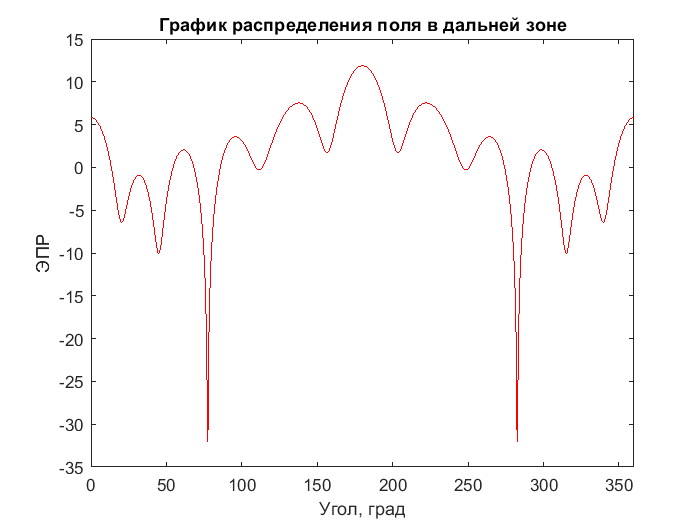

title('График распределения поля в дальней зоне'); 
xlim([0 360])
xlabel('Угол, град'); 
ylabel('ЭПР');

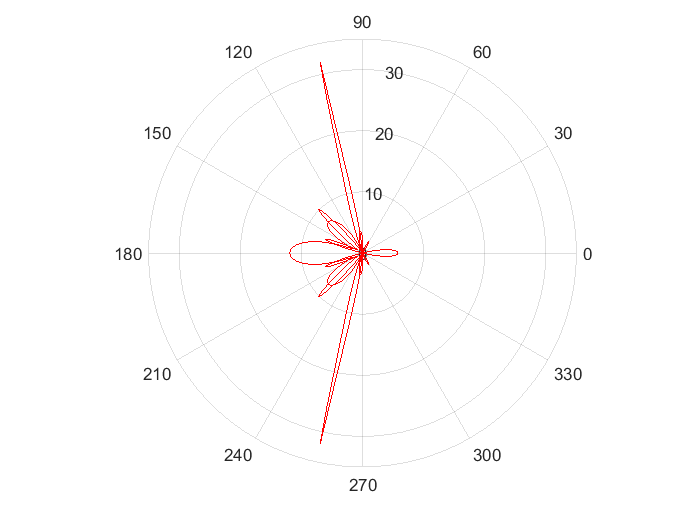


figure;
polarplot(phi_rad_for_graf_DA, RCS,'r-');

### Используемые функции

function [dJ_calc] = dJ(n,x)
    dJ_calc = n/x*besselj(n,x) - besselj(n+1,x);
end
function [dH_calc] = dH(n,x)
    dH_calc = n/x*besselh(n,1,x) - besselh(n+1,1,x);
end